clear ;
close all;

tic
load ryan3_data.mat
toc 

Elapsed time is 1.753880 seconds.


% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')

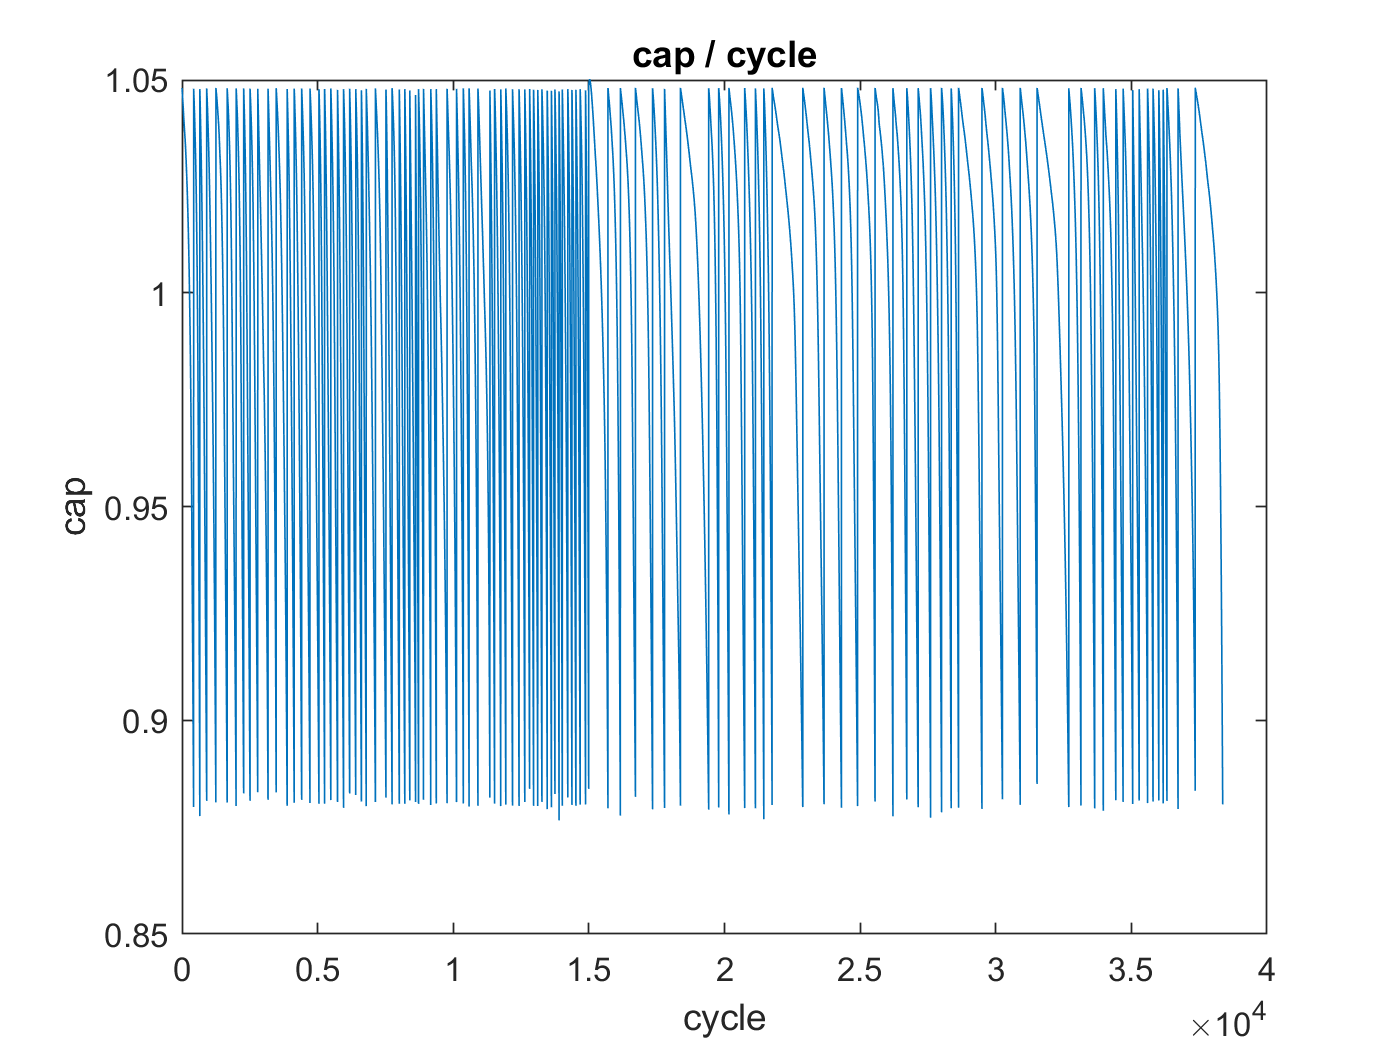

% https://kr.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html#TimeSeriesForecastingUsingDeepLearningExample-4
figure
plot(Y_trainValid_SOH')
xlabel("cycle")
ylabel("cap")
title("cap / cycle")


dataTrain = Y_trainValid_SOH'

dataTrain =     1.0479    1.0478    1.0477    1.0476    1.0475    1.0474    1.0473    1.0472    1.0471    1.0470    1.0469    1.0468    1.0467    1.0466    1.0465    1.0463    1.0462    1.0461    1.0460    1.0459    1.0458    1.0457    1.0456    1.0455    1.0454    1.0453    1.0452    1.0451    1.0450    1.0449    1.0448    1.0447    1.0446    1.0445    1.0443    1.0442    1.0441    1.0440    1.0439    1.0438    1.0437    1.0436    1.0435    1.0434    1.0432    1.0431    1.0430    1.0429    1.0428    1.0427


dataTest = Y_test_SOH'

dataTest =     1.0477    1.0476    1.0474    1.0473    1.0471    1.0470    1.0468    1.0467    1.0465    1.0464    1.0462    1.0460    1.0459    1.0457    1.0456    1.0454    1.0452    1.0451    1.0449    1.0447    1.0446    1.0444    1.0442    1.0441    1.0439    1.0437    1.0436    1.0434    1.0432    1.0431    1.0429    1.0427    1.0425    1.0423    1.0422    1.0420    1.0418    1.0416    1.0414    1.0412    1.0410    1.0408    1.0406    1.0404    1.0402    1.0399    1.0397    1.0395    1.0393    1.0391


mu = mean(Cap)

mu = 0.9975

sig = std(Cap)

sig = 0.0462


dataTrainStandardized = (dataTrain - mu) / sig

dataTrainStandardized =     1.0898    1.0876    1.0854    1.0833    1.0811    1.0789    1.0767    1.0745    1.0723    1.0702    1.0680    1.0658    1.0635    1.0613    1.0591    1.0568    1.0546    1.0523    1.0501    1.0478    1.0455    1.0433    1.0410    1.0387    1.0365    1.0342    1.0319    1.0296    1.0273    1.0251    1.0228    1.0205    1.0182    1.0158    1.0135    1.0112    1.0088    1.0065    1.0041    1.0017    0.9994    0.9970    0.9945    0.9921    0.9897    0.9872    0.9847    0.9822    0.9797    0.9772



XTrain = dataTrainStandardized(1:end-1)

XTrain =     1.0898    1.0876    1.0854    1.0833    1.0811    1.0789    1.0767    1.0745    1.0723    1.0702    1.0680    1.0658    1.0635    1.0613    1.0591    1.0568    1.0546    1.0523    1.0501    1.0478    1.0455    1.0433    1.0410    1.0387    1.0365    1.0342    1.0319    1.0296    1.0273    1.0251    1.0228    1.0205    1.0182    1.0158    1.0135    1.0112    1.0088    1.0065    1.0041    1.0017    0.9994    0.9970    0.9945    0.9921    0.9897    0.9872    0.9847    0.9822    0.9797    0.9772


YTrain = dataTrainStandardized(2:end)

YTrain =     1.0876    1.0854    1.0833    1.0811    1.0789    1.0767    1.0745    1.0723    1.0702    1.0680    1.0658    1.0635    1.0613    1.0591    1.0568    1.0546    1.0523    1.0501    1.0478    1.0455    1.0433    1.0410    1.0387    1.0365    1.0342    1.0319    1.0296    1.0273    1.0251    1.0228    1.0205    1.0182    1.0158    1.0135    1.0112    1.0088    1.0065    1.0041    1.0017    0.9994    0.9970    0.9945    0.9921    0.9897    0.9872    0.9847    0.9822    0.9797    0.9772    0.9746


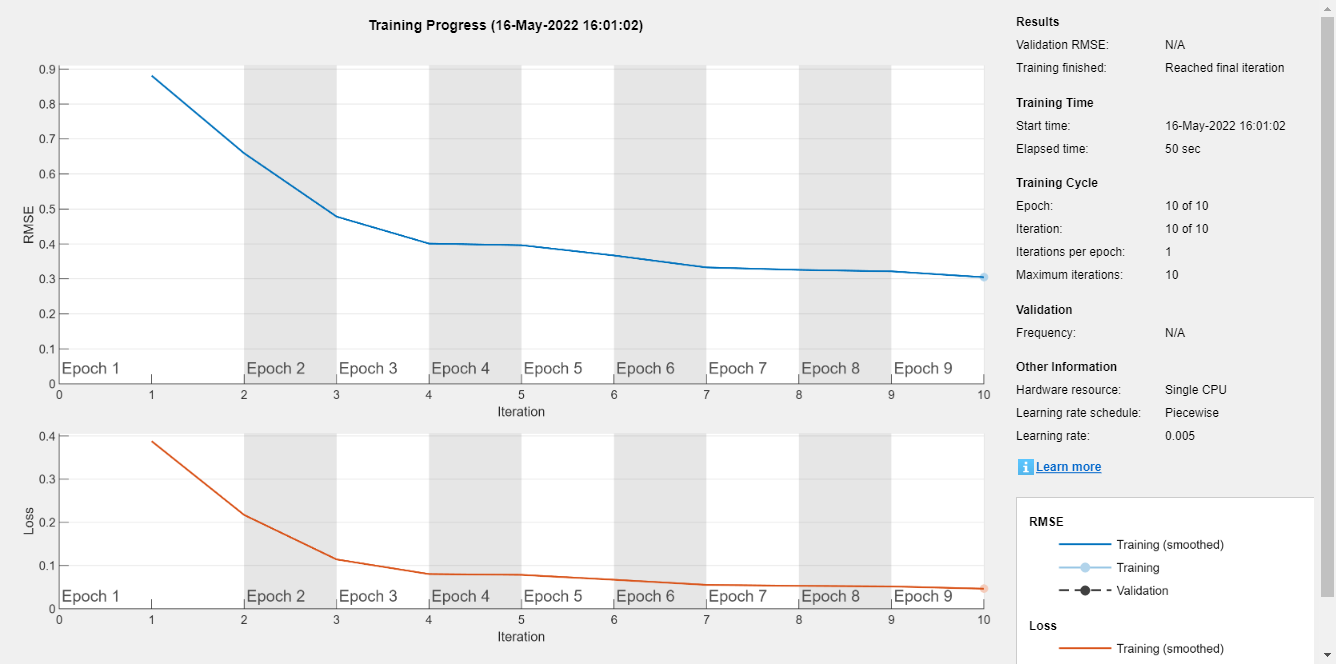

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}



numFeatures = 1;
numResponses = 1;
numHiddenUnits = 50;
%numHiddenUnits = 200;
max_epoc = 10;
%max_epoc = 250;


layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];


options = trainingOptions('adam', ...
    'MaxEpochs',max_epoc, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

tic
net = trainNetwork(XTrain,YTrain,layers,options)

toc

Elapsed time is 55.433077 seconds.



dataTestStandardized = (dataTest - mu) / sig

dataTestStandardized =     1.0865    1.0832    1.0800    1.0767    1.0735    1.0702    1.0670    1.0637    1.0604    1.0570    1.0537    1.0503    1.0469    1.0434    1.0400    1.0365    1.0329    1.0294    1.0258    1.0223    1.0187    1.0151    1.0115    1.0079    1.0042    1.0006    0.9969    0.9932    0.9895    0.9858    0.9820    0.9781    0.9743    0.9703    0.9664    0.9623    0.9582    0.9541    0.9498    0.9455    0.9412    0.9367    0.9323    0.9277    0.9231    0.9184    0.9137    0.9089    0.9041    0.8992


XTest = dataTestStandardized(1:end-1)

XTest =     1.0865    1.0832    1.0800    1.0767    1.0735    1.0702    1.0670    1.0637    1.0604    1.0570    1.0537    1.0503    1.0469    1.0434    1.0400    1.0365    1.0329    1.0294    1.0258    1.0223    1.0187    1.0151    1.0115    1.0079    1.0042    1.0006    0.9969    0.9932    0.9895    0.9858    0.9820    0.9781    0.9743    0.9703    0.9664    0.9623    0.9582    0.9541    0.9498    0.9455    0.9412    0.9367    0.9323    0.9277    0.9231    0.9184    0.9137    0.9089    0.9041    0.8992


# 예측값만으로 추가 예측하는 것이 아니라

# 관측값을 기반으로 다음을 예측

net = predictAndUpdateState(net,XTrain)

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


[net,YPred] = predictAndUpdateState(net,YTrain(end))

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


YPred = single
-2.1027


numTimeStepsTest = numel(XTest)

numTimeStepsTest = 4487

for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu

YPred = 1×4487 single row vector
    0.9002    0.9028    0.9052    0.9076    0.9100    0.9122    0.9143    0.9162    0.9180    0.9196    0.9210    0.9223    0.9235    0.9246    0.9256    0.9266    0.9274    0.9282    0.9289    0.9295    0.9301    0.9307    0.9312    0.9317    0.9321    0.9325    0.9329    0.9332    0.9335    0.9338    0.9341    0.9344    0.9346    0.9348    0.9351    0.9353    0.9354    0.9356    0.9358    0.9359    0.9361    0.9362    0.9363    0.9364    0.9365    0.9366    0.9367    0.9368    0.9369    0.9370



YTest = dataTest(2:end)

YTest =     1.0476    1.0474    1.0473    1.0471    1.0470    1.0468    1.0467    1.0465    1.0464    1.0462    1.0460    1.0459    1.0457    1.0456    1.0454    1.0452    1.0451    1.0449    1.0447    1.0446    1.0444    1.0442    1.0441    1.0439    1.0437    1.0436    1.0434    1.0432    1.0431    1.0429    1.0427    1.0425    1.0423    1.0422    1.0420    1.0418    1.0416    1.0414    1.0412    1.0410    1.0408    1.0406    1.0404    1.0402    1.0399    1.0397    1.0395    1.0393    1.0391    1.0388


rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
0.0745


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest-1)

idx =        38366       38367       38368       38369       38370       38371       38372       38373       38374       38375       38376       38377       38378       38379       38380       38381       38382       38383       38384       38385       38386       38387       38388       38389       38390       38391       38392       38393       38394       38395       38396       38397       38398       38399       38400       38401       38402       38403       38404       38405       38406       38407       38408       38409       38410       38411       38412       38413       38414       38415


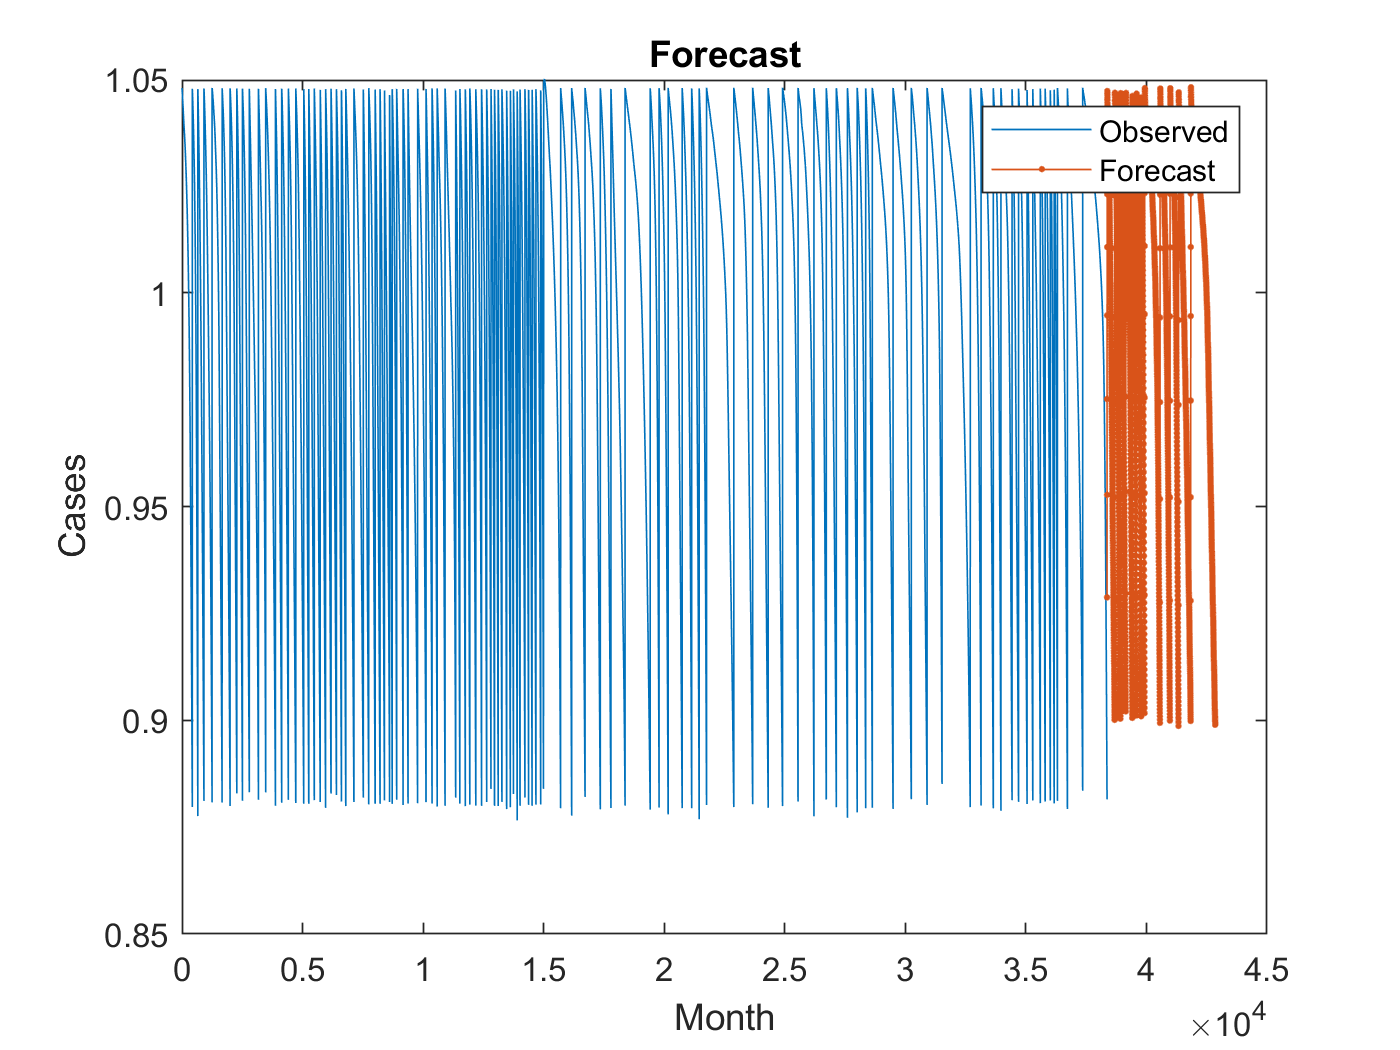

%plot(idx,[dataTrain(numTimeStepsTrain) YPred],'.-')
plot(idx,YPred,'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

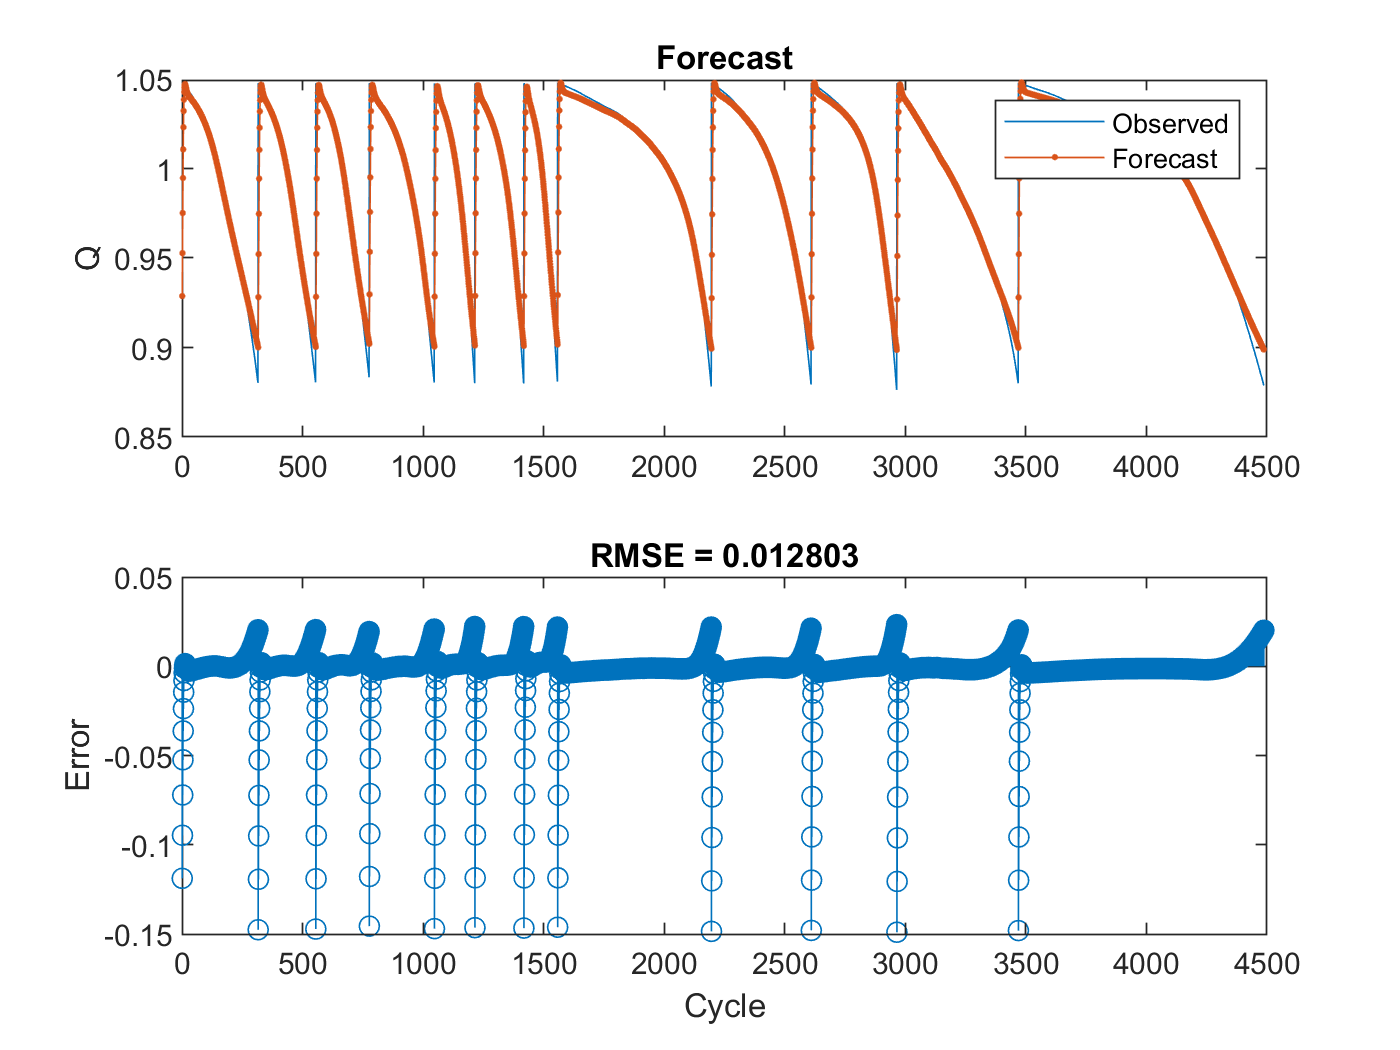

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Q")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Cycle")
ylabel("Error")
title("RMSE = " + rmse)


net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))

rmse = 0.0128

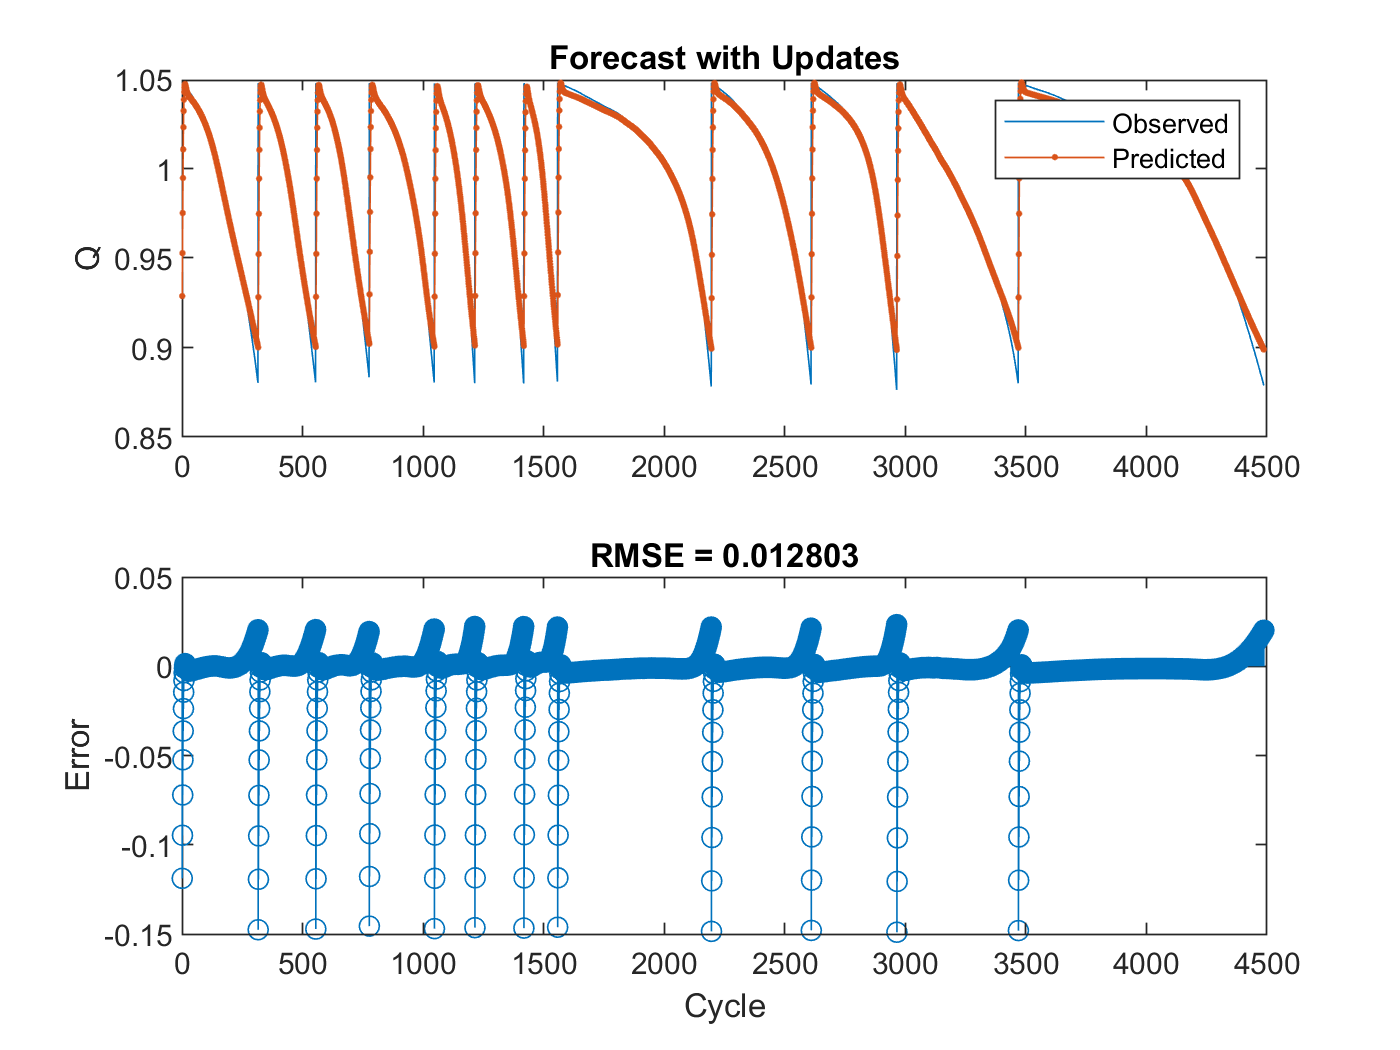


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Q")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Cycle")
ylabel("Error")
title("RMSE = " + rmse)

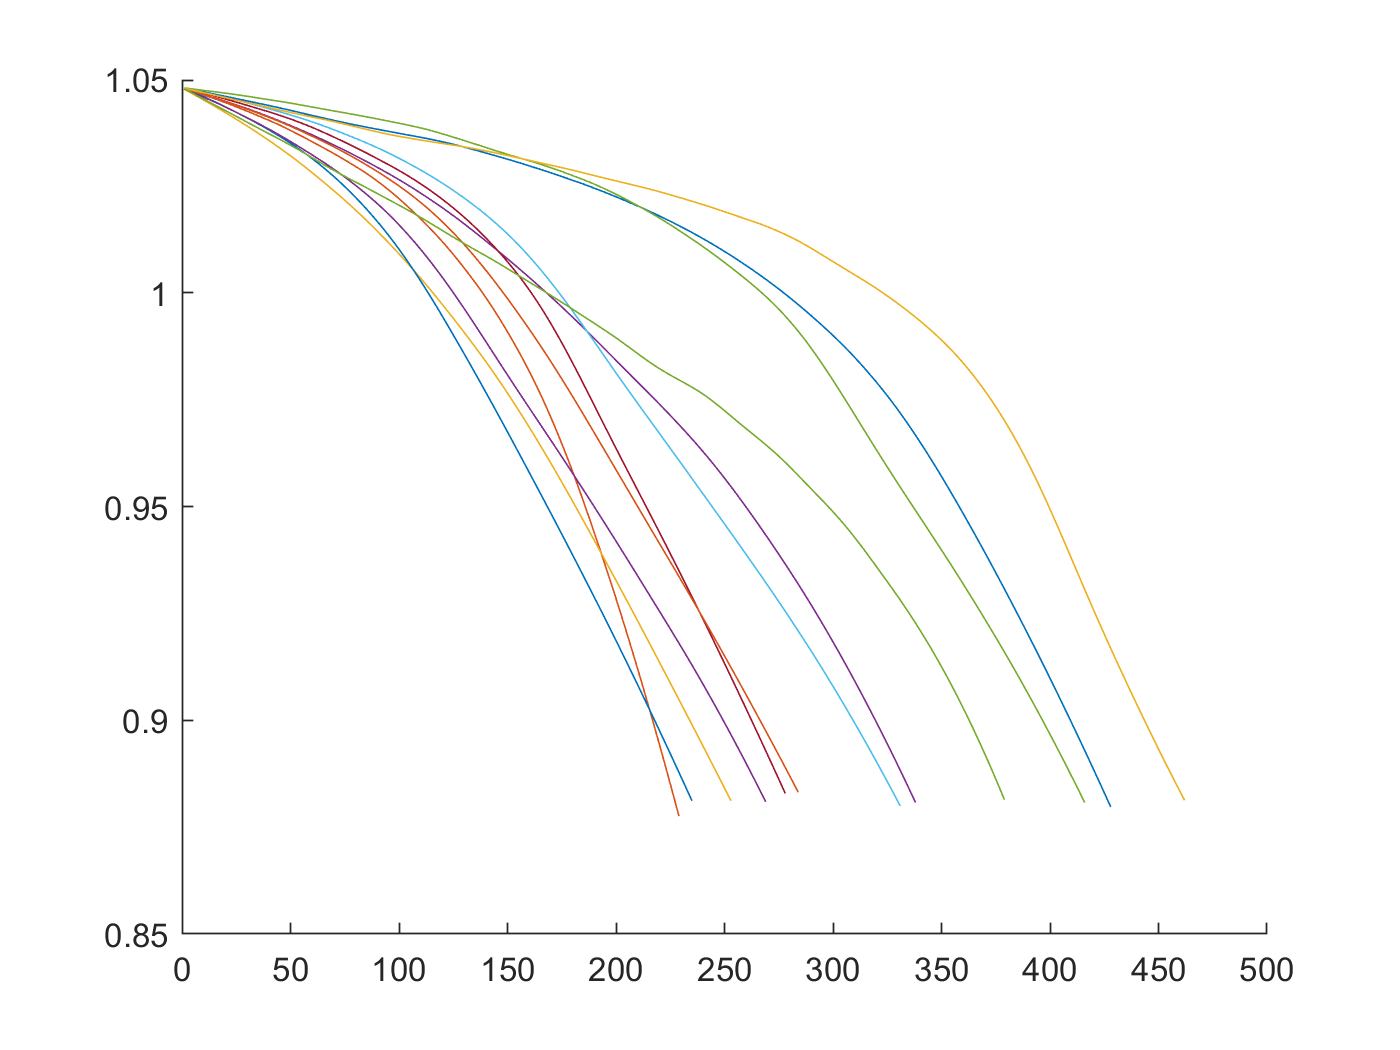

capPatternChange = zeros();
capPatternChange = [];
for i = 1:length(battery_testset)
    cap_temp = battery_testset(i).QDischargeSmooth;
    if i == 1
        capPatternChange = cap_temp;
    else 
        capPatternChange = vertcat(capPatternChange,cap_temp);
    end 
end

capPatternChange = capPatternChange'

capPatternChange =     1.0476    1.0473    1.0469    1.0465    1.0462    1.0458    1.0454    1.0450    1.0446    1.0442    1.0438    1.0434    1.0430    1.0426    1.0421    1.0417    1.0413    1.0408    1.0404    1.0399    1.0395    1.0390    1.0385    1.0381    1.0376    1.0371    1.0366    1.0361    1.0356    1.0351    1.0345    1.0340    1.0334    1.0329    1.0323    1.0317    1.0311    1.0305    1.0299    1.0293    1.0287    1.0281    1.0274    1.0268    1.0261    1.0254    1.0247    1.0240    1.0233    1.0226


# 사용자 패턴 변경에 따른 SOH데이타 

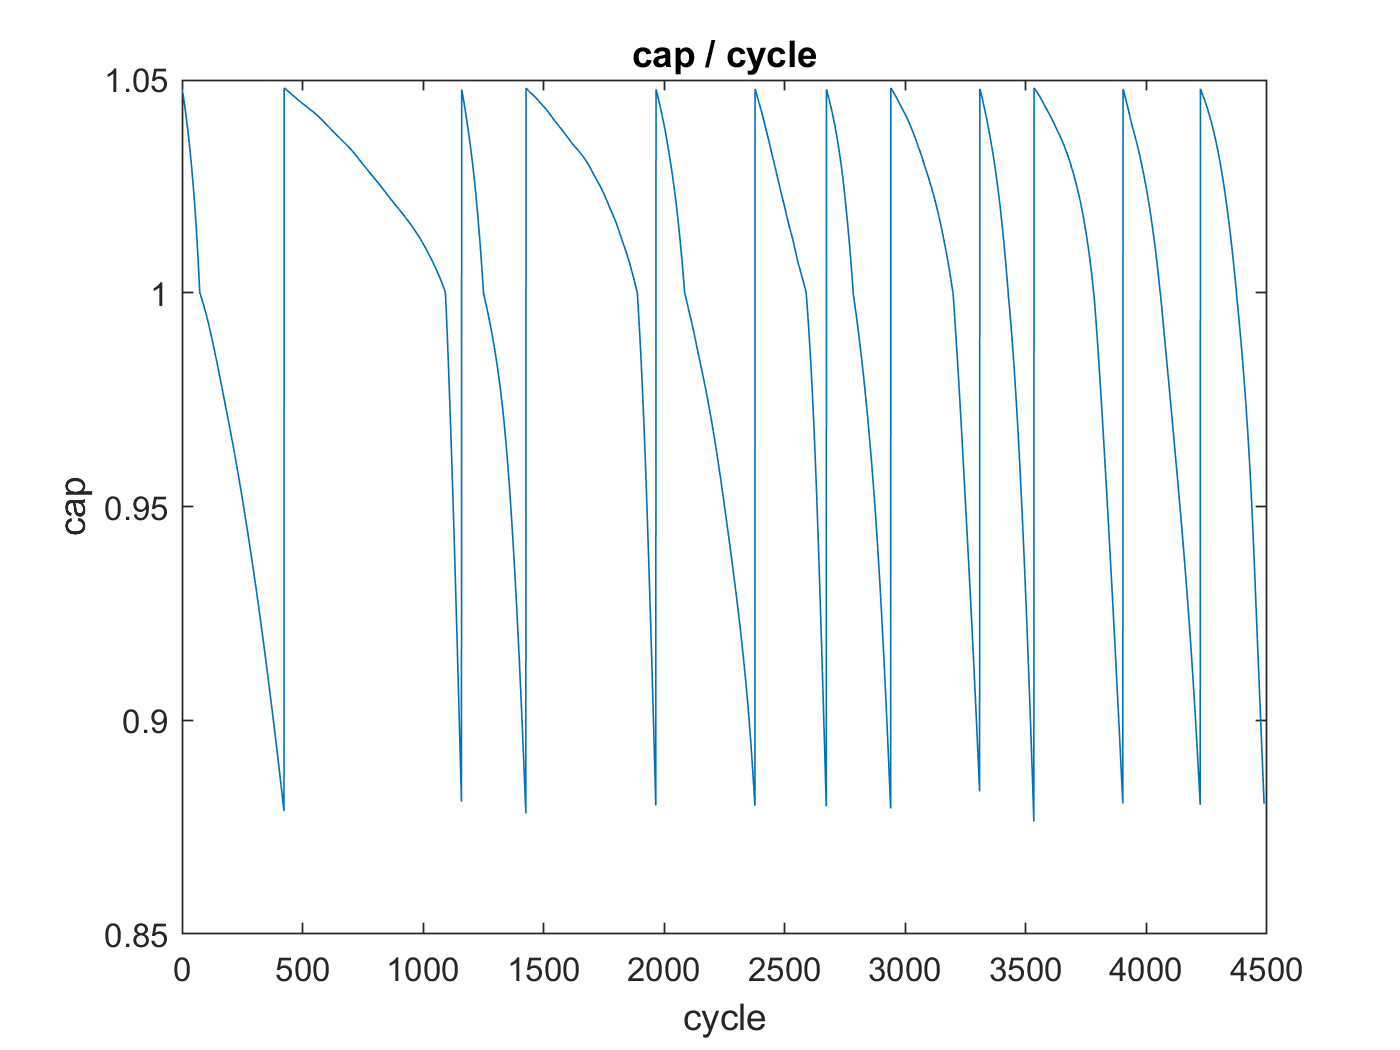

figure
plot(capPatternChange)
xlabel("cycle")
ylabel("cap")
title("cap / cycle")

# 테스트셋으로 평가

# 노멀라이즈 => 평균/표준변차로 +/- 1부터 최대 3까지. 예측

dataTrainStandardized_test = (capPatternChange - mu) / sig;
max(dataTrainStandardized_test)
min(dataTrainStandardized_test)
 
XTrain = dataTrainStandardized_test(1:end-1);
YTrain = dataTrainStandardized_test(2:end);

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

# 디노말라이즈 후 성능평가 

# 각 배터리의테스트데이타데이타 사이에 패팅이 넣고 학습후 

# 이를 나중에 제가하면 성능이 더 좋아질것으로 보임


YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))

rmse = 0.0156

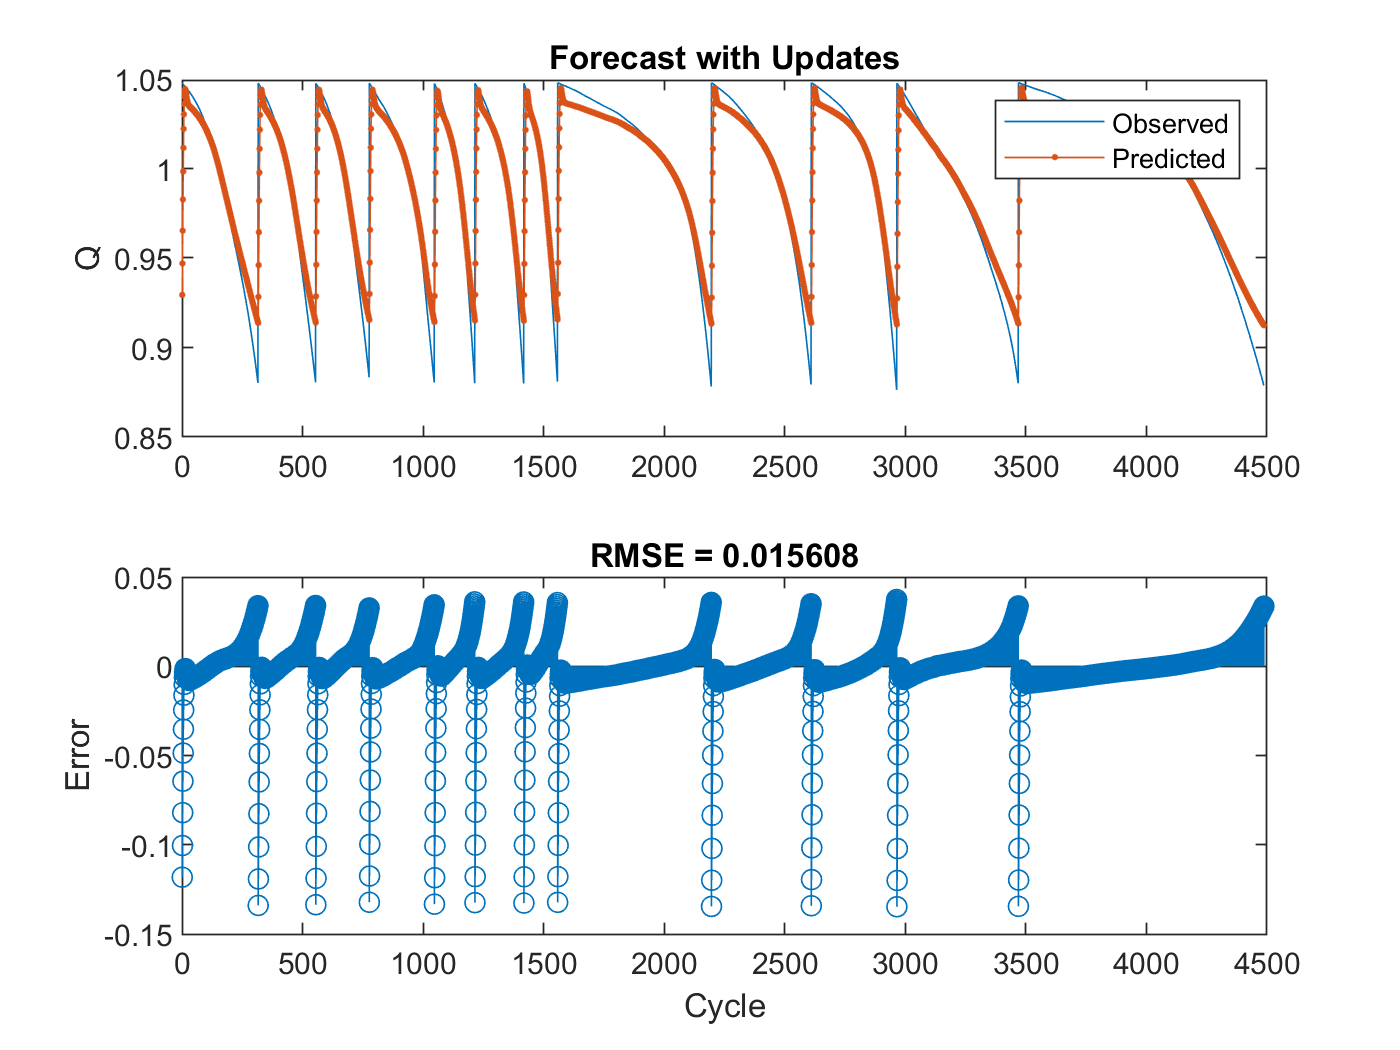


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Q")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Cycle")
ylabel("Error")
title("RMSE = " + rmse)

dataset_test_org_count = length(battery_testset_org)

dataset_test_org_count = 12

dataset_test_change_count = length(battery_testset)

dataset_test_change_count = 12

cap_train_org_all = zeros()

cap_train_org_all = 0

cap_train_change_all = zeros()

cap_train_change_all = 0

cap_train_org_all_norm = zeros()

cap_train_org_all_norm = 0

cap_train_change_all_norm = zeros()

cap_train_change_all_norm = 0

XTrainAll = zeros()

XTrainAll = 0

YTrainAll = zeros()

YTrainAll = 0



numFeatures = 1;
numResponses = 1;
numHiddenUnits = 50;
%numHiddenUnits = 200;
max_epoc = 10;
max_epoc_test = 50;
%max_epoc = 250;

i = 1

i = 1

cap_train_org = battery_testset_org(i).QDischargeSmooth';
cap_train_change = battery_testset(i).QDischargeSmooth';
cap_train_org_norm =  (cap_train_org - mu) / sig;
cap_train_change_norm =  (cap_train_change - mu) / sig;
XTrain = cap_train_org_norm(1:end-1);
YTrain = cap_train_org_norm(2:end); 
    
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];


options = trainingOptions('adam', ...
    'MaxEpochs',max_epoc_test, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
    

net_org = zeros()

net_org = 0

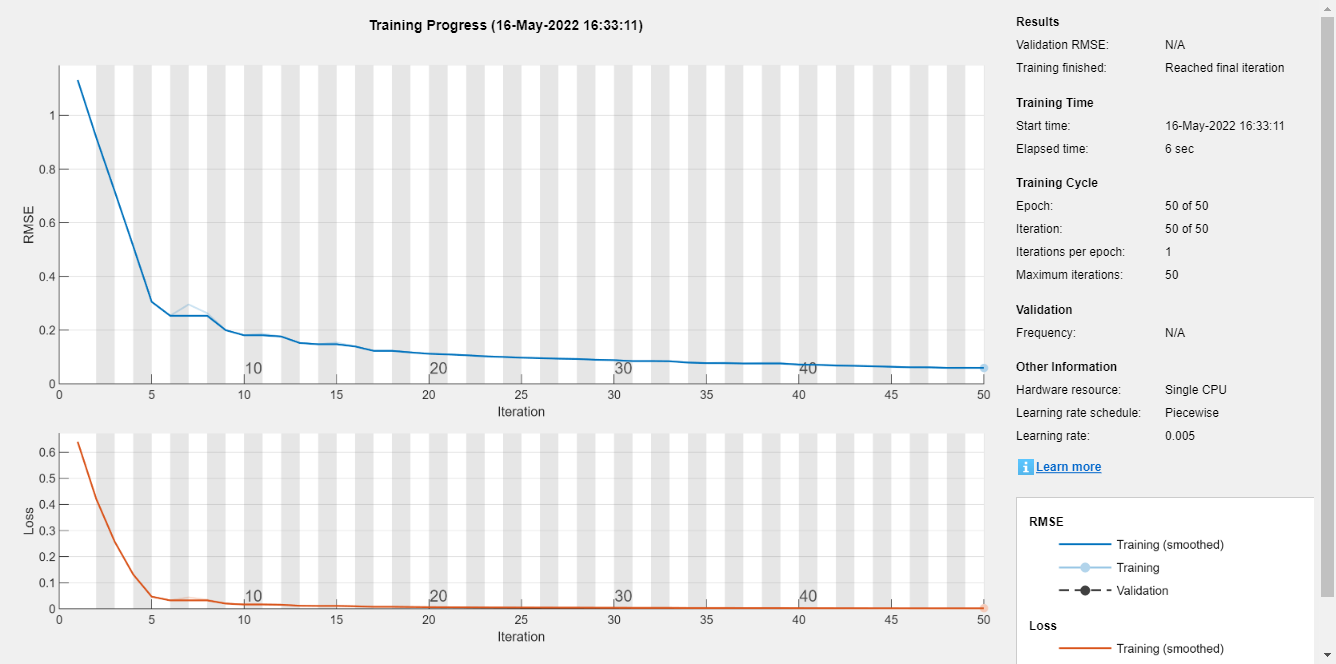

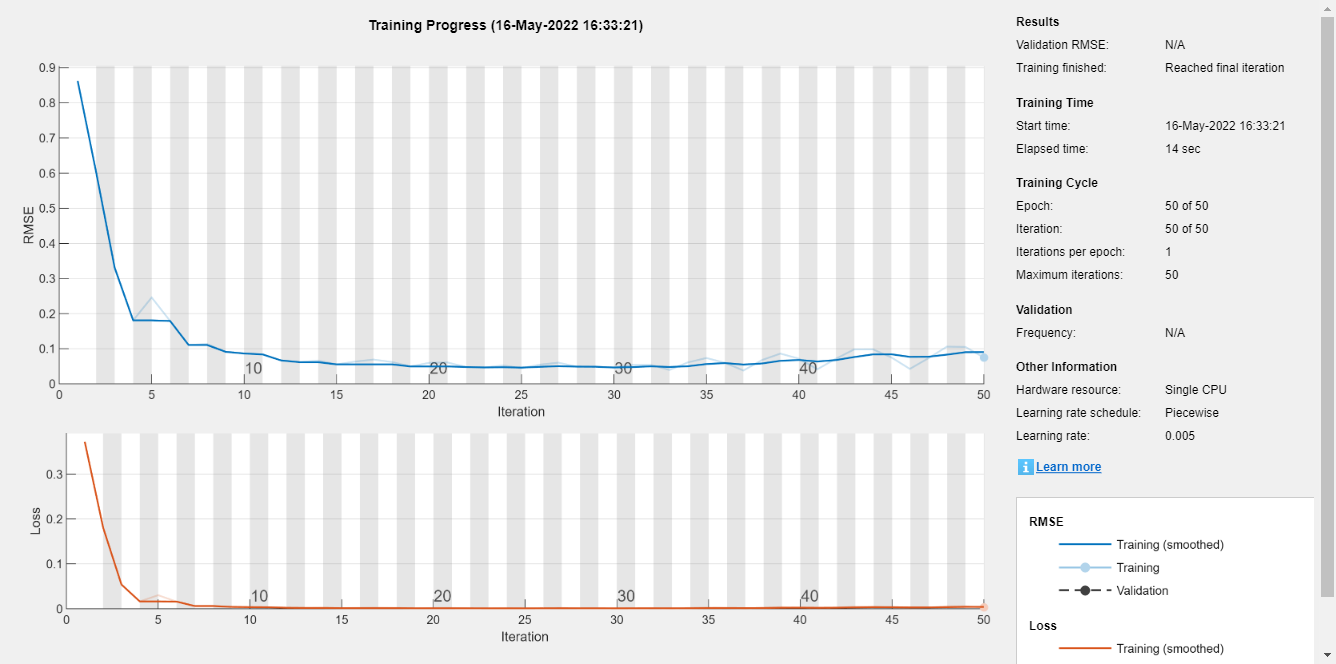

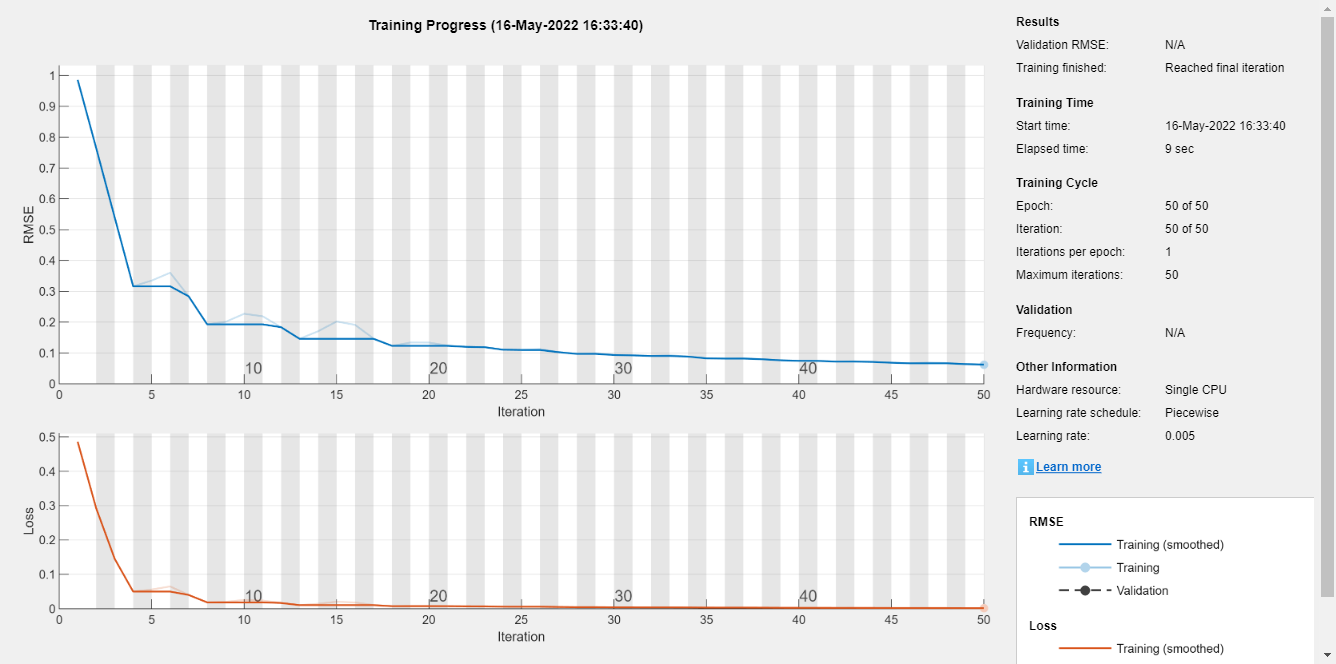

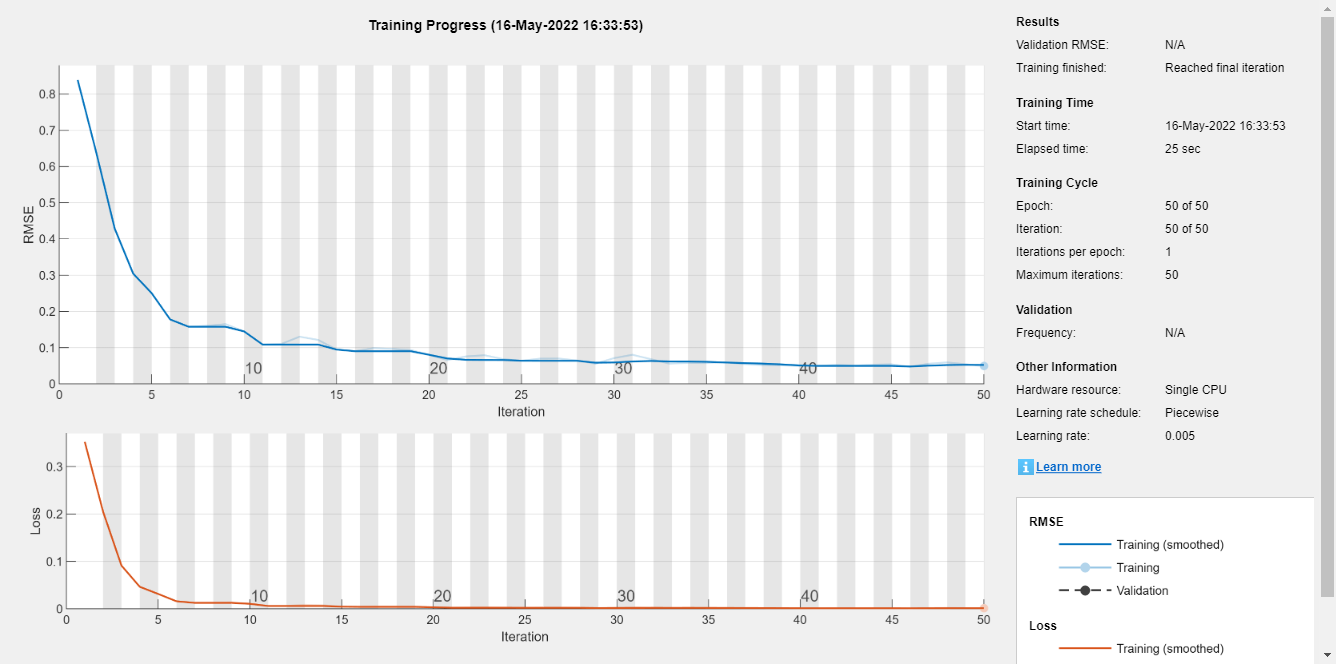

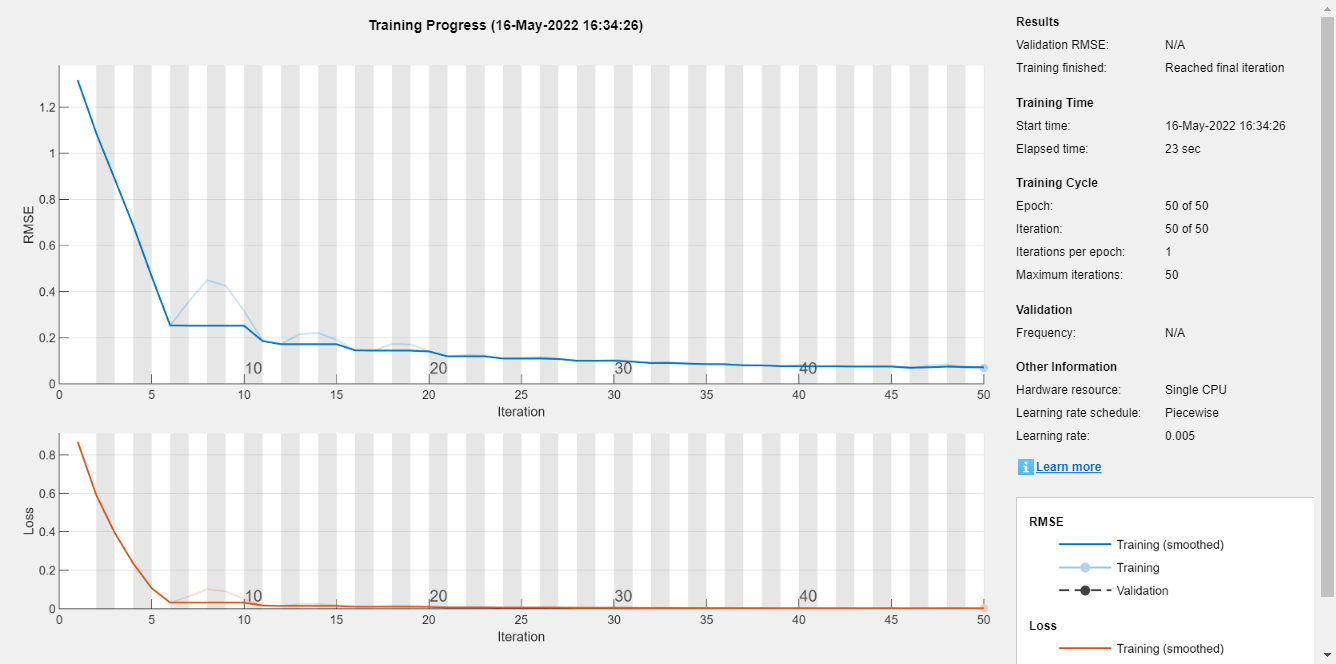

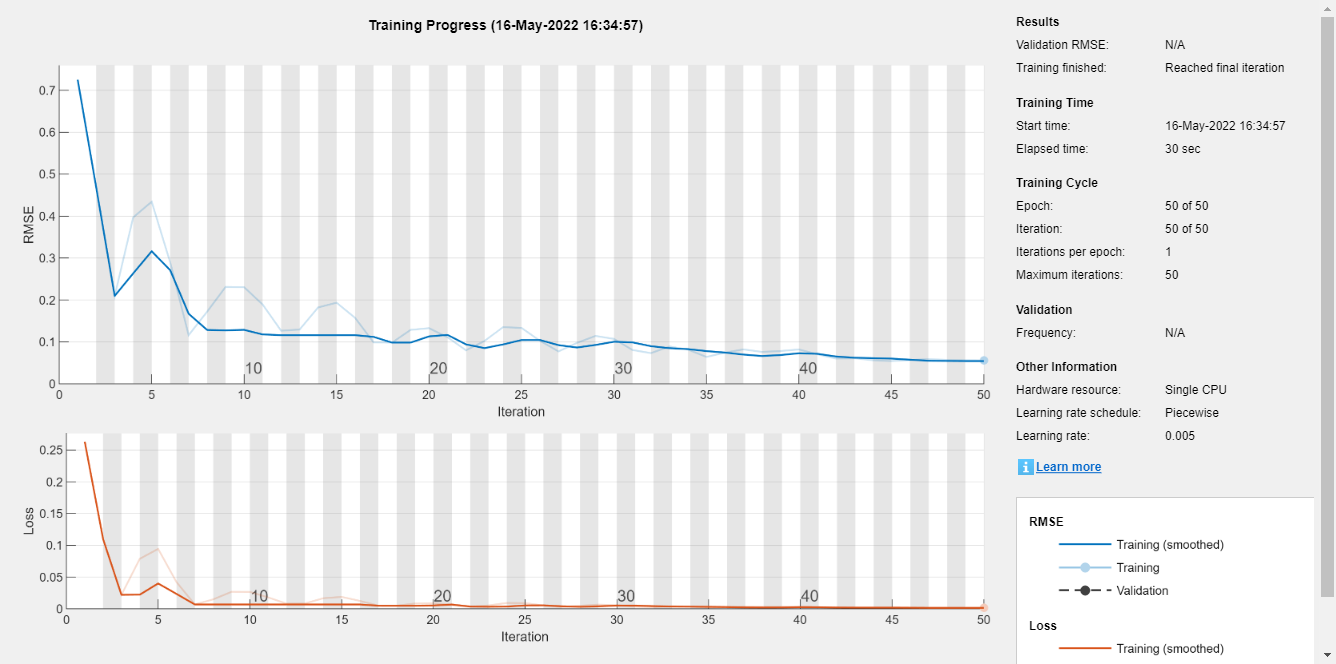

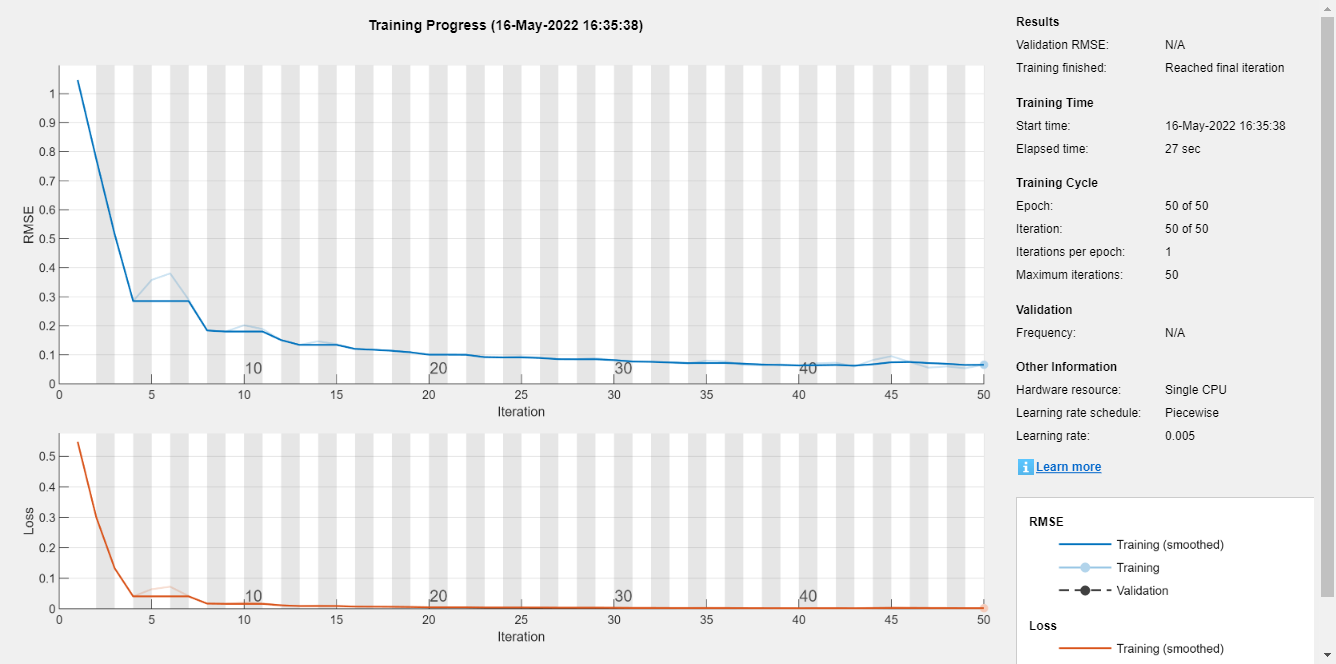

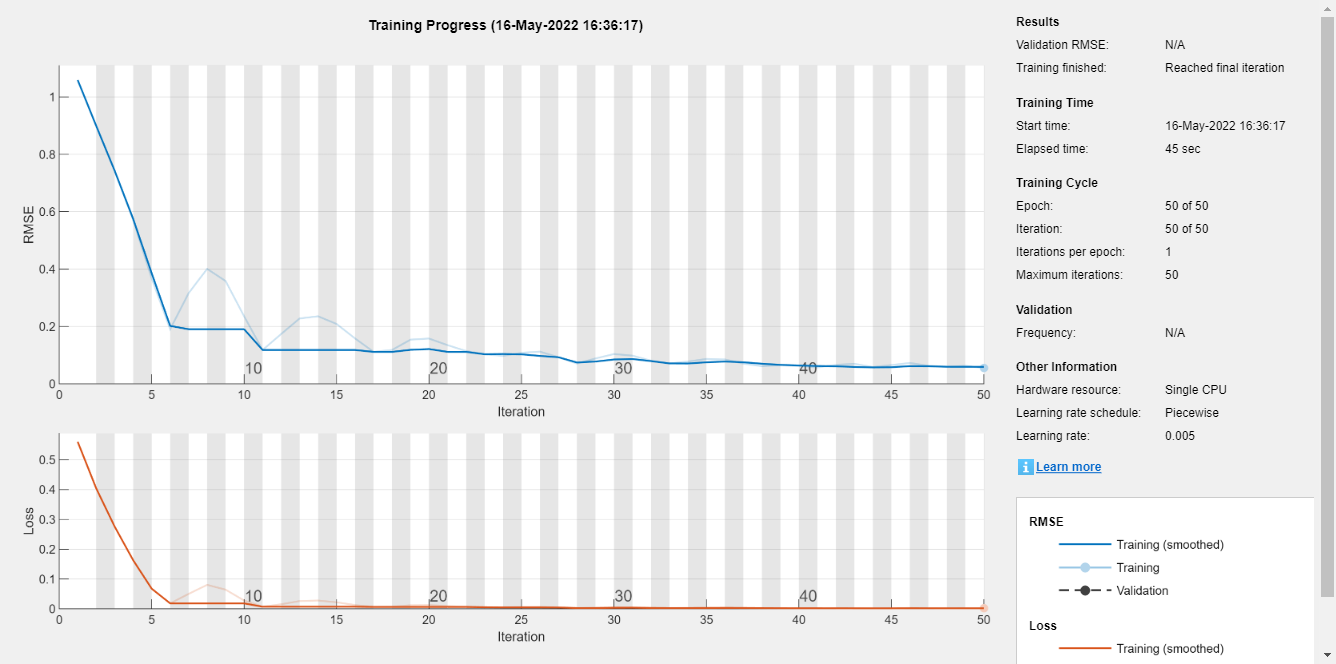

for i = 1:dataset_test_org_count
    cap_train_org = battery_testset_org(i).QDischargeSmooth';
    cap_train_change = battery_testset(i).QDischargeSmooth';
    cap_train_org_norm =  (cap_train_org - mu) / sig;
    cap_train_change_norm =  (cap_train_change - mu) / sig;
    XTrain = cap_train_org_norm(1:end-1);
    YTrain = cap_train_org_norm(2:end);    

%     cap_train_org_all(i,:) = vertcat(cap_train_org_all,cap_train_org)
%     cap_train_change_all(i,:) = vertcat(cap_train_change_all,cap_train_org)
%     cap_train_org_all_norm(i,:) = vertcat(cap_train_org_all_norm,cap_train_org)
%     cap_train_change_all_norm(i,:) = vertcat(cap_train_change_all_norm,cap_train_org) 
%     XTrainAll(i,:) = vertcat(XTrainAll,XTrain)  
%     YTrainAll(i,:) = vertcat(YTrainAll,YTrain)  
    
    cap_train_org_all = horzcat(cap_train_org_all,cap_train_org);
    cap_train_change_all = horzcat(cap_train_change_all,cap_train_org);
    cap_train_org_all_norm = horzcat(cap_train_org_all_norm,cap_train_org);
    cap_train_change_all_norm = horzcat(cap_train_change_all_norm,cap_train_org)  ;
    XTrainAll = horzcat(XTrainAll,XTrain);
    YTrainAll = horzcat(YTrainAll,YTrain);
    
    if i == 1
        net_org = trainNetwork(XTrain,YTrain,layers,options);
    else
        net_org(i,:) = trainNetwork(XTrain,YTrain,layers,options);
    end
end

for i=1:dataset_test_org_count

  
    cap_train_change_norm = (battery_testset(i).QDischargeSmooth') - mu /sig ;
    XTrain = cap_train_change_norm(1:end-1);
    YTrain = cap_train_change_norm(2:end);     
    

    net(i,:) = resetState(net(i,:));
    net(i,:) = predictAndUpdateState(net(i,:),XTrain);
    
    YPred = [];
    numTimeStepsTest = numel(XTest);
    for i = 1:numTimeStepsTest
        [net(i,:),YPred(:,i)] = predictAndUpdateState(net(i,:),XTest(:,i),'ExecutionEnvironment','cpu');
    end
    
    YPred = sig*YPred + mu;
    
    rmse = sqrt(mean((YPred-YTest).^2))
end 

Index in position 1 exceeds array bounds (must not exceed 2).